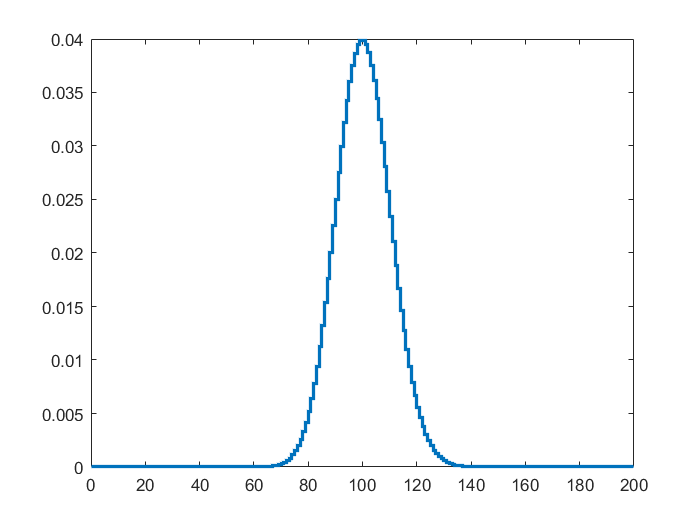

% Lab 6
% Kyle McEleney

clear all; close all;
% Problem 1

% Poisson distribution used in lieu of LHC data
Background = makedist('Poisson', 'Lambda', 100);

% Define a sequence of numbers to plot the distribution on
x = 0:200;

% Plot the pdf of the background distribution using stairs because it's a
% Poisson distribution.
stairs(x,pdf(Background,x),"LineWidth",2);

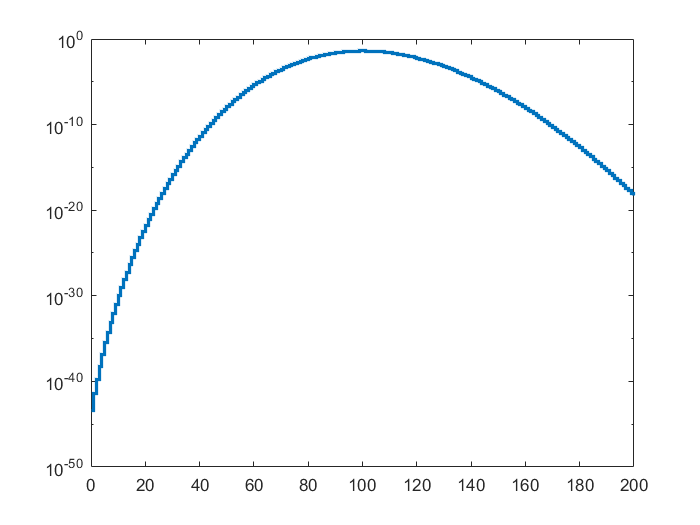

% Probability distribution on a log scale to better visualize the pdf.
stairs(x,pdf(Background,x),"LineWidth",2);
set(gca,'YScale','log')


% Determine the sigma value associated with the given value of 53. Since
% it's a discrete distribution, 53 is the smallest discrete value that
% will yield at least -5 sigma. Guess and check was used to settle upon
% this value.
norminv(cdf(Background, 53))

ans = -5.0878

% Determine the sigma value associated with the given value of 154. Since
% it's a discrete distribution, 154 is the smallest discrete value that
% will yield at least +5 sigma. Guess and check was used to settle upon
% this value.
norminv(cdf(Background, 154))

ans = 5.0575

% Problem 2

% Determine what value corresponds to 8 sigma given the Poisson
% distribution using Guess and Check.
norminv(cdf(Background, 190))

ans = 8.0414

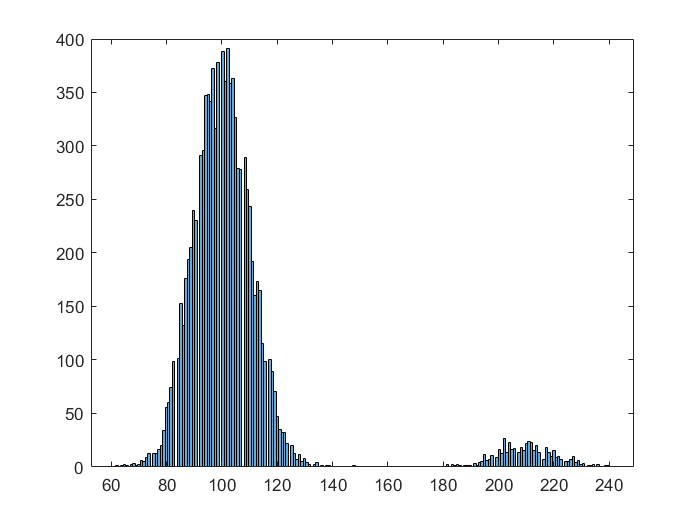

% Generate a random Poisson distribution centered around 100.
signal(1,1:10000) = poissrnd(100,1,10000);

% Add significant values to a subset of the distribution in order to
% produce a signal distribution.
signal(1:500)=signal(1:500) + 110;


% Fit distribution to the data
background_pdf = fitdist(signal.', 'Poisson');
histogram(signal.', 200)

% 2a The observed signal appears to be significantly more bright than the background data presented by the Poisson distribution. 
norminv(cdf(Background, 140))

ans = 3.8302

% When looking at the histogram generated, the largest visible value of the
% background data set is somewhere around 140 counts which corresponds to a
% sigma value of 3.8.

norminv(cdf(Background, 180))       

ans = 7.2394

% The approximate smallest value seen in the signal data distribution is
% somewhere around 180. This corresponds to a sigma value near 7.2 which
% corrseponds to a probability of PROBABILITY when generated by the base
% Poisson distribution.

% 2b The observed signal appears to be biased since it's always weaker than
% the injected signal by the method that the injected signal was generated
% by (translating a distribution of points from the observed distribution).
% The observed signal distribution is not symmetric since Poisson
% distributions are not symmetric.  


